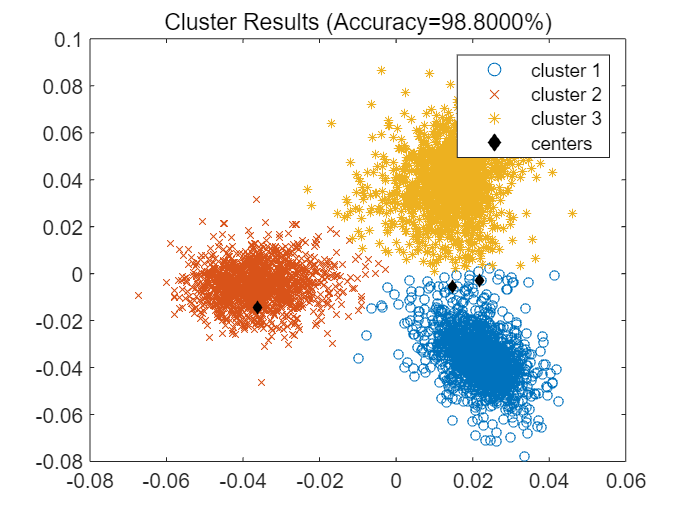

load data_LDA.mat
%in data variable,1:1500 represent digit3 1501:3000 represent
%digit6 and 3001:4500 represent digit9
data=[reshape(projection_1,[4500,1]) reshape(projection_2,[4500,1])];
label=zeros(1,4500);
label(1:1500)=3;
label(1501:3000)=6;
label(3001:4500)=9;


%randomly set initial centers
cluster1=[];cluster2=[];cluster3=[];%represent digit3 digit6 digit9
center=[data(unidrnd(size(data,1)),:); data(unidrnd(size(data,1)),:);data(unidrnd(size(data,1)),:)];
center_new=[[];[];[]];

distance=pdist2(center,data);
[~,class]=min(distance);
cluster1=data(class==1,:);
cluster2=data(class==2,:);
cluster3=data(class==3,:);
center_new=[mean(cluster1);mean(cluster2);mean(cluster3)];

%Iteration
while(~isequal(center,center_new))
    center=center_new;
    distance=pdist2(center,data,'cosine');
    [~,class]=min(distance);
    cluster1=data(class==1,:);
    cluster2=data(class==2,:);
    cluster3=data(class==3,:);
    center_new=[mean(cluster1);mean(cluster2);mean(cluster3)];
end

confus=zeros(3,3);
for i=1:size(data,1)
    if(class(:,i)==1 && label(:,i)==3)
        confus(1,1)=confus(1,1)+1;
    elseif(class(:,i)==1 && label(:,i)==6)
        confus(2,1)=confus(2,1)+1;
    elseif(class(:,i)==1 && label(:,i)==9)
        confus(3,1)=confus(3,1)+1;
    elseif(class(:,i)==2 && label(:,i)==3)
        confus(1,2)=confus(1,2)+1;
    elseif(class(:,i)==2 && label(:,i)==6)
        confus(2,2)=confus(2,2)+1;
    elseif(class(:,i)==2 && label(:,i)==9)
        confus(3,2)=confus(3,2)+1;
    elseif(class(:,i)==3 && label(:,i)==3)
        confus(1,3)=confus(1,3)+1;
    elseif(class(:,i)==3 && label(:,i)==6)
        confus(2,3)=confus(2,3)+1;
    elseif(class(:,i)==3 && label(:,i)==9)
        confus(3,3)=confus(3,3)+1;
    end
end

accur=sum(max(confus))/size(label,2);

figure(1)
colormap("summer")
scatter(cluster1(:,1),cluster1(:,2),20,'o');hold on
scatter(cluster2(:,1),cluster2(:,2),20,'x');hold on
scatter(cluster3(:,1),cluster3(:,2),20,'*');hold on
scatter(center(1,1),cluster1(1,2),20,'k','d','filled');hold on
scatter(center(2,1),cluster1(2,2),20,'k','d','filled');hold on
scatter(center(3,1),cluster1(3,2),20,'k','d','filled');hold off
box on
legend('cluster 1','cluster 2','cluster 3','centers')
str = sprintf('Cluster Results (Accuracy=%.4f%%)',accur*100);
title(str)

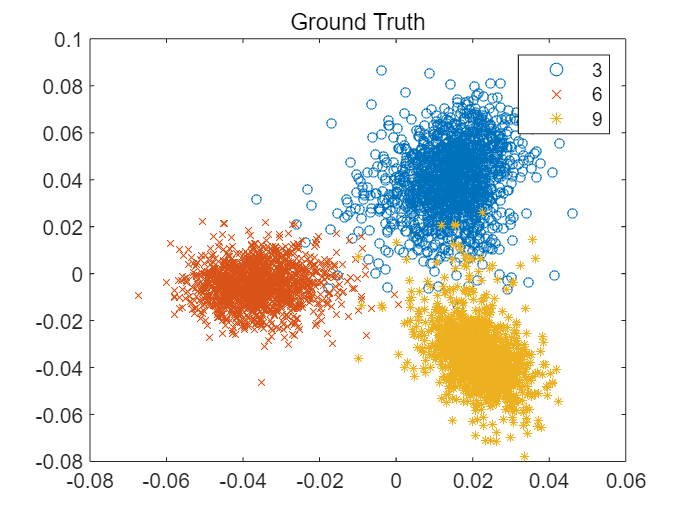


figure(2)
scatter(data(label==3,1),data(label==3,2),20,'o');hold on
scatter(data(label==6,1),data(label==6,2),20,'x');hold on
scatter(data(label==9,1),data(label==9,2),20,'*');hold off
box on
legend('3','6','9')
title('Ground Truth')